Loading the image

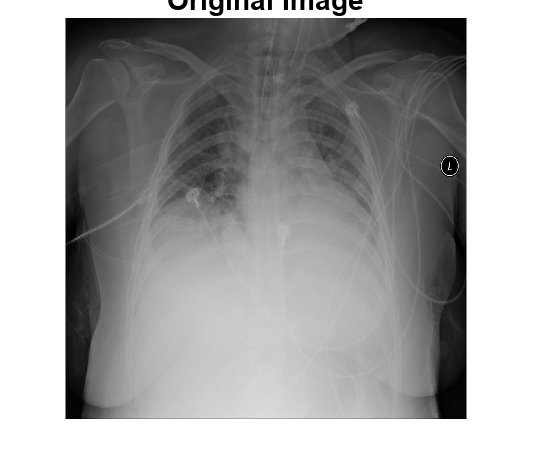

I = dicomread("lung_opacity.dcm"); %already binary
imshow(I);
title("Original Image");

Thresholding image

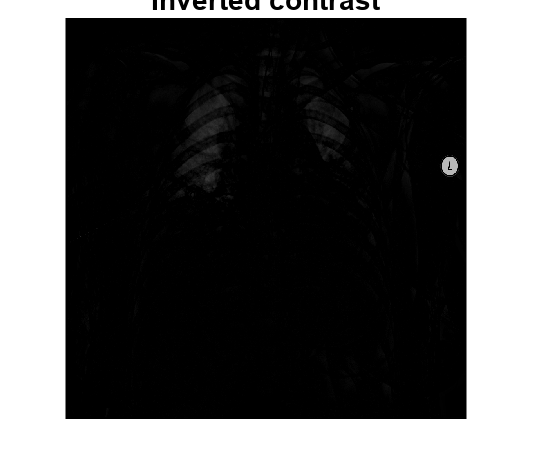

contrast = imadjust(I); %increase contrast of image
Inverse_I = 255 - contrast; %inverse color to make the brightest things black
Inverse_I = imclearborder(Inverse_I); %smoothens
imshow(Inverse_I);
title("Inverted contrast");

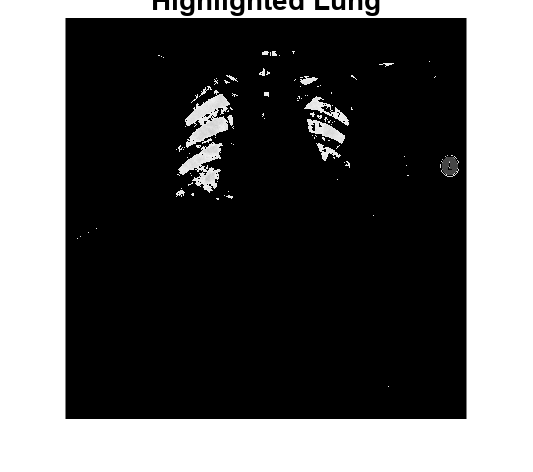


Lung = 255 - Inverse_I; %Highlights everything but lungs
Lung(Lung > 240) = 0; %Anything past a certain brightness becomes 0
imshow(Lung);
title("Highlighted Lung");

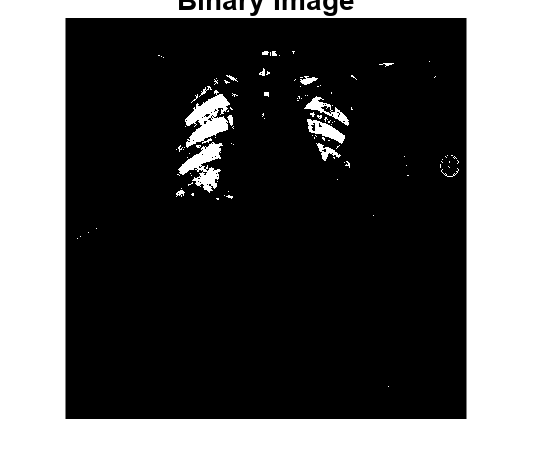


BW = imbinarize(Lung); %making a completely black and white image
imshow(BW);
title("Binary Image");

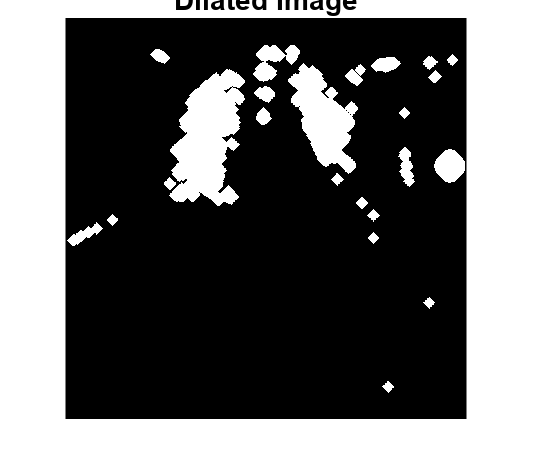


seD = strel('diamond',15); %filling in all gaps in lungs
BWdil = imdilate(BW, seD);
BWdil = imfill(BWdil, 'holes');
imshow(BWdil);
title("Dilated Image");

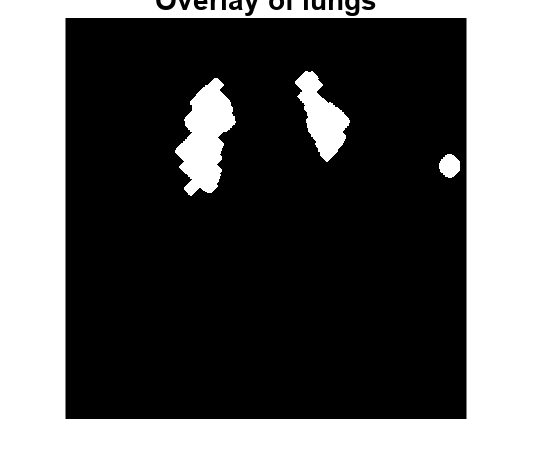


seD = strel('diamond',15); %eroding image to get rid of all the "noise" 
BWerode=imerode(BWdil,seD);
BWerode=imerode(BWerode,seD);
BWfinal = imdilate(BWerode, seD); %bringing lungs back to original size
seC = strel('disk',3); %smoothing out edges
BWfinal = imdilate(BWfinal, seC);
imshow(BWfinal);
title("Fully isolated and highlighted lung");

overlay = labeloverlay(I,BWfinal); %overlaying isolated lungs with original image
title("Overlay of lungs");

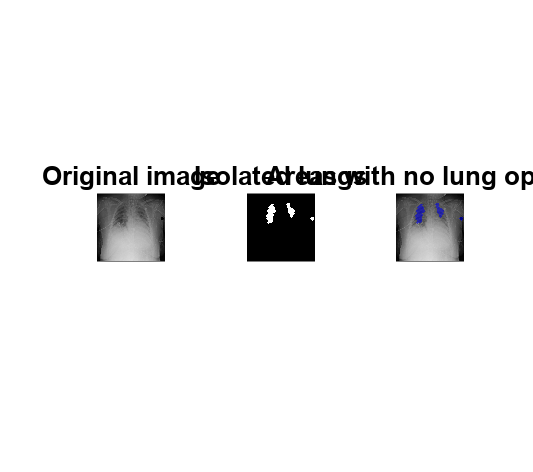


subplot(1,3,1); %plotting original, isolated, and areas with no lung opacity for comparisons
    imshow(I);
    title("Original image");
subplot(1,3,2);
    imshow(BWfinal);
    title("Isolated lungs");
subplot(1,3,3);
    imshow(overlay);
    title("Areas with no lung opacity");